绘制分泳道的热图

热图是一种简单直观呈现NTATS的方法。每组表现为一个泳道，泳道内是一张热图，用渐变颜色表示数值大小。

## 语法

## 示例

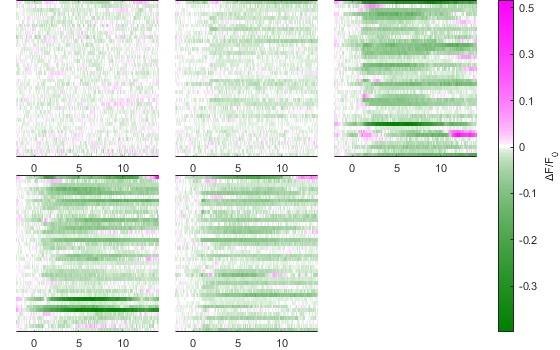

## 输入参数

NTATS(:,:,:)MATLAB.DataTypes.NDTable，作图数据，第1维细胞，第2维时间，第3维分组。将为每组对应一个泳道，泳道内第1维是细胞，第2维是时间。一般应从HeatmapSort的返回值中取得。

Array(:,:,:)，原始数组，第1维细胞，第2维时间，第3维分组。将为每组对应一个泳道，泳道内第1维是细胞，第2维是时间。一般应从HeatmapSort的返回值中取得。

Flags1,Flags2,…(1,1)UniExp.Flags，指定功能旗帜，可选以下旗帜：

- HideXAxis，隐藏X轴

- HideYAxis，隐藏Y轴

- ScaleColor，扭曲颜色图，使得较小数值获得较大对比度

- SymmetricColormap，采用对称颜色图，确保从高到低颜色梯度保持一致。如果不指定此参数，将强制最大正值对应到最大色，最小负值对应到最小色，这可能会导致正数段与负数段颜色梯度不同。

### 名称值参数

#### ImagescStyle(1,:)cell=cell(1,0)

本函数调用imagesc绘图，此处指定要传递给imagesc的其它参数。建议至少设置XData，保证XY坐标尺度正确。

#### LMHColor(3,3)double=[0,0.5,0;1,1,1;1,0,1]

指定最小、0、最大三个数值大小节点的颜色，其它数值将执行插值，得到颜色映射表。

如果指定了ScaleColor旗帜，将使用平方根插值而不是线性插值。

如果数据最大值的绝对值大于最小值的绝对值，最小颜色将不会出现在图上，最小值将用最小色和0色之间的某个颜色表示，以确保线性插值斜率均等；如果最大值的绝对值小于最小值的绝对值，反之亦然。要改变这种行为，指定SymmetricColormap旗帜，以使最大值和最小值一定对应最大色和最小色；但这将使得正数段和负数段的颜色梯度不同。

#### SubTitles(1,:)string

每个泳道的小标题。如不指定，将查找NTATS.Dimensions.IndexNames{3}作为小标题，如果也为空，就不显示小标题。

#### Layout(1,1)matlab.graphics.layout.TiledChartLayout=tiledlayout('flow',TileSpacing='tight',Padding='tight')

指定泳道布局对象，可用tiledlayout函数取得

#### TitleArguments(1,:)cell={'Interpreter','none'}

用于显示泳道小标题的其它格式参数，将传递给内置title函数。

#### CLim(1,2)

颜色棒对应的数值范围。如果不指定此参数，将采用所有泳道的最小值和最大值作为数值范围。

## 返回值

Layout(1,1)matlab.graphics.layout.TiledChartLayout，泳道布局对象，可用于作图后期修饰

Axes(:,:)matlab.graphics.axis.Axes，每个泳道的坐标轴对象，可用于作图后期修饰。注意，第1维对应泳道布局水平排列，第2维对应泳道布局垂直分行。

**See also** [UniExp.HeatmapSort](matlab:doc UniExp.HeatmapSort) [UniExp.Flags](matlab:edit UniExp.Flags) [imagesc](matlab:doc imagesc) [tiledlayout](matlab:doc tiledlayout) [MATLAB.DataTypes.NDTable](matlab:doc MATLAB.DataTypes.NDTable) [title](matlab:doc title)

function [Layout,Axes]=LanearHeatmap(Data,Flags,options)
arguments
	Data
end
arguments(Repeating)
    Flags
end
arguments
	options.ImagescStyle=cell(1,0)
    options.LMHColor=[0,0.5,0;1,1,1;1,0,1];
	options.SubTitles
	options.Layout=tiledlayout('flow',TileSpacing='tight',Padding='tight')
	options.TitleArguments={'Interpreter','none'}
	options.CLim
end
HasFlags=num2cell(ismember([UniExp.Flags.HideXAxis,UniExp.Flags.HideYAxis,UniExp.Flags.ScaleColor,UniExp.Flags.SymmetricColormap],[Flags{:}]));
[HideXAxis,HideYAxis,ScaleColor,SymmetricColormap]=HasFlags{:};
HasSubTitles=isfield(options,'SubTitles');
IsNDTable=isa(Data,'MATLAB.DataTypes.NDTable');
if HasSubTitles
	SubTitles=options.SubTitles;
elseif IsNDTable&&height(Data.Dimensions)>=3
	SubTitles=Data.Dimensions.IndexNames{3};
	HasSubTitles=~isempty(SubTitles);
end
if IsNDTable
	Data=Data.Data;
end
NumLanes=size(Data,3);
if isfield(options,'CLim')
	Min=options.CLim(1);
	Max=options.CLim(2);
else
	[Min,Max]=bounds(Data,'all');
end
Limit=[Min,Max];
Steps=linspace(Min,Max,256);
LMHColor=options.LMHColor;
LowSteps=Steps(Steps<0)';
HighSteps=Steps(Steps>0)';
if SymmetricColormap&&Min<0&&Max>0
	if Max+Min>0
		LMHColor(1,:)=LMHColor(2,:)*(1+Min)-LMHColor(1,:)*Min/Max;
	elseif Max+Min<0
		LMHColor(3,:)=(LMHColor(3,:)*Max-LMHColor(2,:)*(Min+Max))/Min;
	end
end
if ScaleColor
	Colormap=[interp2(1:3,LowSteps,MATLAB.ElMat.LinSpace(LMHColor(1,:),LMHColor(2,:),numel(LowSteps),1),1:3,rescale(-sqrt(-LowSteps),min(LowSteps),max(LowSteps)));interp2(1:3,HighSteps,MATLAB.ElMat.LinSpace(LMHColor(2,:),LMHColor(3,:),numel(HighSteps),1),1:3,rescale(sqrt(HighSteps),min(HighSteps),max(HighSteps)))];
else
	Colormap=[interp2(1:3,LowSteps,MATLAB.ElMat.LinSpace(LMHColor(1,:),LMHColor(2,:),numel(LowSteps),1),1:3,rescale(LowSteps,min(LowSteps),max(LowSteps)));interp2(1:3,HighSteps,MATLAB.ElMat.LinSpace(LMHColor(2,:),LMHColor(3,:),numel(HighSteps),1),1:3,rescale(HighSteps,min(HighSteps),max(HighSteps)))];
end
%防止浮点误差造成的范围外数值
Colormap=clip(Colormap,0,1);
RealAxes=gobjects(NumLanes,1);
Layout=options.Layout;
for a=1:NumLanes
	Ax=nexttile(Layout);
	imagesc(Data(:,:,a),options.ImagescStyle{:});
	clim(Ax,Limit);
	if HideXAxis
		Ax.XAxis.Visible="off";
	end
	if HideYAxis
		Ax.YAxis.Visible="off";
	end
	box off
	Ax.TickDir='out';
	colormap(Ax,Colormap);
	if HasSubTitles
		title(SubTitles(a),options.TitleArguments{:});
	end
	RealAxes(a)=Ax;
end
drawnow;
Axes=gobjects(Layout.GridSize)';
Axes(1:NumLanes)=RealAxes;
end